# Optimal Threshold of SVD Recomposition

*Author: Koby Taswell*

First load our file and let's add some noise with the Gaussian Patter

path = 'Kingfisher.jpg';

I = imread(path);

n = max(size(I))

n = 1724

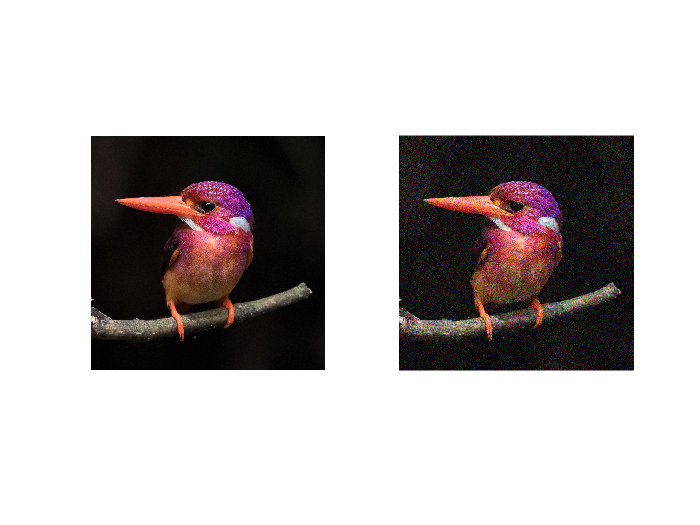


Inoisey = imnoise(I, "gaussian");

subplot(1,2,1)
imshow(I);

subplot(1,2,2)
imshow(Inoisey)

ImseUint = immse(I, Inoisey)

ImseUint = 429.5799


I = im2double(I);
Inoisey = im2double(Inoisey);

ImseDoubleNoisey = immse(I, Inoisey)

ImseDoubleNoisey = 0.0066

We see that the image is fairly noisey. Though it seems like it is higher when the data is not in double precision. So perhaps MSE is not appropriate here...

Next we calculate the SVD of each color channel RGB,

[UnoiseyR, SnoiseyR, VnoiseyR] = svd(Inoisey(:, :, 1)); % Red Channel
[UnoiseyG, SnoiseyG, VnoiseyG] = svd(Inoisey(:, :, 2)); % Green Channel
[UnoiseyB, SnoiseyB, VnoiseyB] = svd(Inoisey(:, :, 3)); % Blue Channel

Now we need to find the threshold which will let us find the rank of our approximation.

As defined in Gavish & Donoho 2014, we can find the threshold of an arbitrary n by n matrix as approximately tau = 2.858*median(S)

First find medians of each color channel:

sMedR = median(diag(SnoiseyR)) % Red single values

sMedR = 2.8481

sMedG = median(diag(SnoiseyG)) % Green single values

sMedG = 2.7287

sMedB = median(diag(SnoiseyB)) % Blue single values

sMedB = 2.6736


c = 2.858 % threshold coefficeint

c = 2.8580


tRed = c*sMedR

tR = 8.1400

tGre = c*sMedG

tG = 7.7986

tBlu = c*sMedB

tB = 7.6412

Set singular values below threshold to zero in each channel

SnoiseyR(SnoiseyR < tRed) = 0;
SnoiseyG(SnoiseyG < tGre) = 0;
SnoiseyB(SnoiseyB < tBlu) = 0;

Reconstruct each matrix

DenoisedRed = UnoiseyR*SnoiseyR*VnoiseyR.';
DenoisedGre = UnoiseyG*SnoiseyG*VnoiseyG.';
DenoisedBlu = UnoiseyB*SnoiseyB*VnoiseyB.';

Idenoised = cat(3, DenoisedRed, DenoisedGre, DenoisedBlu);

Display for Visual Assessment

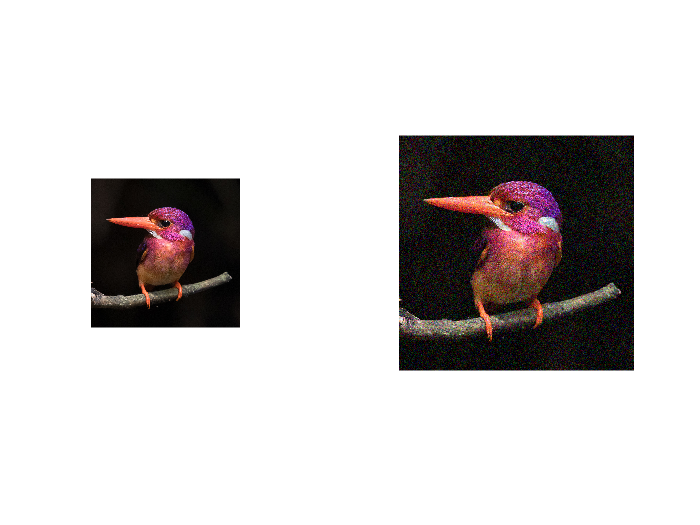

subplot(1,3,1)
imshow(I);

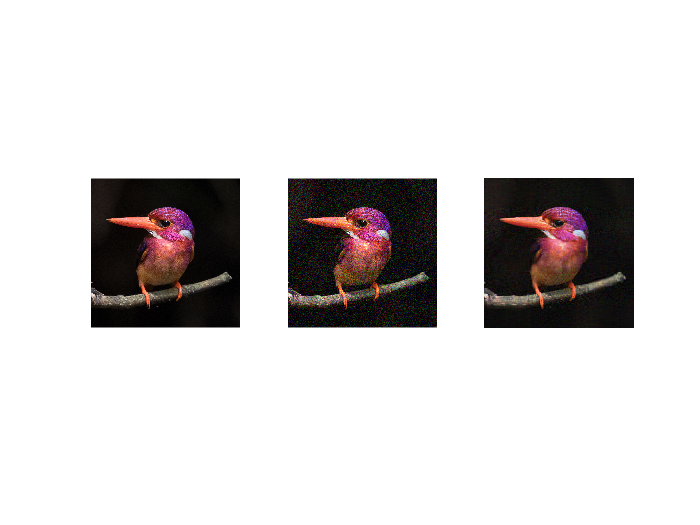


subplot(1,3,2)
imshow(Inoisey);

subplot(1,3,3)
imshow(Idenoised)

And calculate new MSE

ImseDoubleDenoise = immse(I, Idenoised)

ImseDoubleDenoise = 0.0022

Test to see if denoised image MSE is smaller than noisey image MSE

testMse = ImseDoubleDenoise < ImseDoubleNoisey

testMse = logical
   1


Let's test to see if we can use the direct estimation via known values of noise for our square matrix

Recalculate our SVDs 

[UnoiseyR, SnoiseyR, VnoiseyR] = svd(Inoisey(:, :, 1)); % Red Channel
[UnoiseyG, SnoiseyG, VnoiseyG] = svd(Inoisey(:, :, 2)); % Green Channel
[UnoiseyB, SnoiseyB, VnoiseyB] = svd(Inoisey(:, :, 3)); % Blue Channel

Assuming this is an accurate measurement of signal-noise-ratio

noiseRed = immse(I(:, :, 1), Inoisey(:, :, 1));
noiseGre = immse(I(:, :, 2), Inoisey(:, :, 2));
noiseBlu = immse(I(:, :, 3), Inoisey(:, :, 3));

d = (4/sqrt(3));

tRedSq = d*sqrt(n)*noiseRed;
tGreSq = d*sqrt(n)*noiseGre;
tBluSq = d*sqrt(n)*noiseBlu;

Now apply our new thresholds

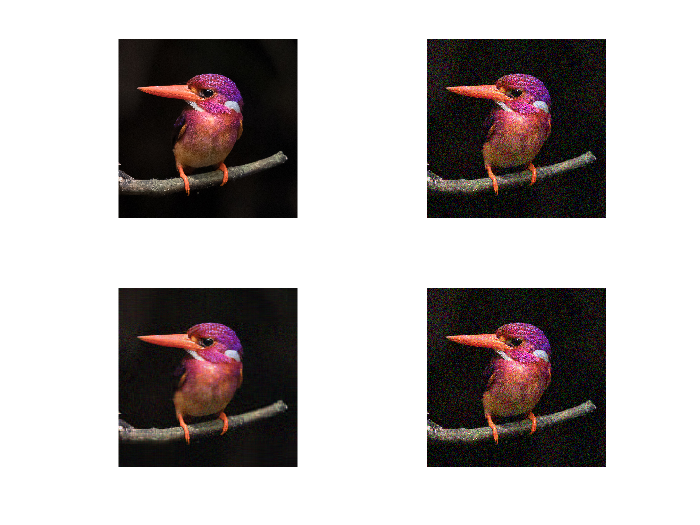

SnoiseyR(SnoiseyR < tRedSq) = 0;
SnoiseyG(SnoiseyG < tGreSq) = 0;
SnoiseyB(SnoiseyB < tBluSq) = 0;

DenoisedRed = UnoiseyR*SnoiseyR*VnoiseyR.';
DenoisedGre = UnoiseyG*SnoiseyG*VnoiseyG.';
DenoisedBlu = UnoiseyB*SnoiseyB*VnoiseyB.';

IdenoiseSq = cat(3, DenoisedRed,DenoisedGre, DenoisedBlu);

subplot(2,2,1)
imshow(I);

subplot(2,2,2)
imshow(Inoisey);

subplot(2,2,3)
imshow(Idenoised);

subplot(2,2,4)
imshow(IdenoiseSq)


ImseDoubleDenoiseSq = immse(I, IdenoiseSq)

ImseDoubleDenoiseSq = 0.0066